## **Trivariate matrix experementation**

Using `bivarnorm.mlx `as a guide I am looking at a three dimensional case of combonations. First we will generate our random trial values. 

ntrials = 10000;

X = randn(3, ntrials);

Next we have to imput our standard deveations and rho values. I am doing thisin vector form so. 

$\vec{\rho} = \left( \begin{array}{c} \rho_{12} \\ \rho_{13} \\ \rho_{23} \end{array} \right)$ and $\vec{\sigma} = \left( \begin{array}{c} \sigma_1 \\ \sigma_2 \\ \sigma_3 \end{array} \right)$ and $\vec{\mu} = \left( \begin{array}{c} \mu_1 \\ \mu_2  \\ \mu_3  \end{array} \right)
$. I chose arbitrary values for these components

rho = [-0.5;0.6;-0.1]; % rho12;rho13;rho23
sigma = [2;1.5;3]; % sigma1;sigma2;sigma3
mu = [1;4;9];
% check to make sure my rho vector is valid (positive semi-definate)—all
% eigenvalues of the below matrix should be positive
rtest = [1, rho(1), rho(2); rho(1), 1, rho(3); rho(2), rho(3), 1];
disp(eig(rtest));

    0.2664
    0.9017
    1.8319



Now we need to find the matrix A that will produce the desired transform. In this case the covariance matrix  $C = \left( \begin{array}{c} \sigma_1^2 & \rho_{12} \sigma_1 \sigma_2 & \rho_{13} \sigma_1 \sigma_3 \\ \rho_{12} \sigma_1 \sigma_2 & \sigma_2^2 & \rho_{23} \sigma_2 \sigma_3 \\ \rho_{13} \sigma_1 \sigma_3 & \rho_{23} \sigma_2 \sigma_3 & \sigma_3^2  \end{array} \right)
$

$C = A A^T$ so se can find A by taking the lower chol

We will then multiply A by X to get our desired Y and plot. 

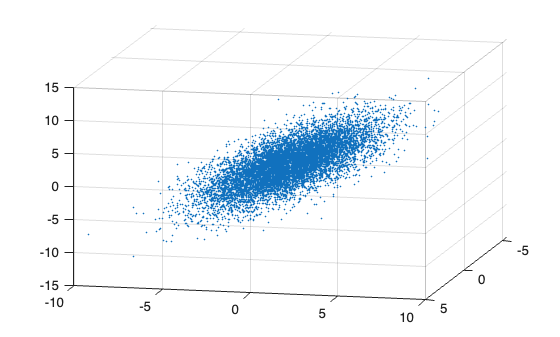

C = [sigma(1)^2, rho(1)*sigma(1)*sigma(2), rho(2)*sigma(1)*sigma(3); rho(1)*sigma(1)*sigma(2), sigma(2)^2, rho(3)*sigma(2)*sigma(3); rho(2)*sigma(1)*sigma(3), rho(3)*sigma(2)*sigma(3), sigma(3)^2];
A = chol(C, "lower");
Y = A * X;
scatter3(Y(1, :),Y(2, :),Y(3, :), 10, '.');

This produced an elipsoid which matched my expectation. 